%-------------------------------------------------------------------------%
%---------------------- 3rd September 2023 -------------------------------%
%-----  Design of controllers with arbitrary convergence time ------------%
%-------------------------------------------------------------------------%

clc;clear all; close all;

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

global Vg rd k1 wd xc yc alpha1 alpha2 alpha3 r1 r2 r3 te r4 alpha4
Vg = 10;
rd = 50;
k1 = 0.5;
wd = 0.25;
xc = 0;
yc = 0;

psi = 0:0.0001: 2*pi ;

xd = xc + rd*cos(psi);
yd = yc + rd*sin(psi);

tspan = [0 60];
x_initial = [100;100;80;-80;70;-70; 90;-95];

options = odeset('RelTol',1e-8,'AbsTol',1e-8);

%%%%%%%%%%%%%%%%%  ode solver   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[t,x] = ode45(@(t,x)fun_circular(t,x) ,tspan, x_initial,options);

% Plot format control variables
lw = 3;            % Line width
ms = 6;            % Marker size
ax_fnt = 17;        % Axis font size
lbl_fnt = ax_fnt; % Label font size
leg_fnt = ax_fnt; % Legend font size
ax_lw = 3;        % Axis line width



figure(1)
h11 = plot(x(:,1),x(:,2),'-r','linewidth',lw);hold on;
h12 = plot(x(:,3),x(:,4),'-g','linewidth',lw);hold on;
h13 = plot(x(:,5),x(:,6),'-b','linewidth',lw);hold on;
h17 = plot(x(:,7),x(:,8),'--k','linewidth',lw);hold on;

hp = plot(xd,yd,'--m','linewidth',lw);hold on;
hp.Annotation.LegendInformation.IconDisplayStyle = 'off' ;
h = plot(xc,yc,'-o','MarkerSize',10,...
    'MarkerEdgeColor','blue',...
    'MarkerFaceColor','magenta'); hold on;
h.Annotation.LegendInformation.IconDisplayStyle = 'off' ;
% plot(x_ini,y_ini,'-o','MarkerSize',10,...
%     'MarkerEdgeColor','blue',...
%     'MarkerFaceColor','green'); hold on;
% plot(x_end,y_end,'-s','MarkerSize',10,...
%     'MarkerEdgeColor','blue',...
%     'MarkerFaceColor','cyan'); hold on;
ax1 = gca;
ax1.FontSize = ax_fnt;
ax1.XColor = 'black';         % Box horizontal lines' color
ax1.YColor = 'black';         % Box vertical lines' color
set(ax1,'linewidth',3)
xlabel(ax1,' $ x, $  m','Fontsize',lbl_fnt);
ylabel(ax1,'$ y, $  m','Fontsize',lbl_fnt);
legend(ax1,'','','','','UAV 1','UAV 2','UAV 3','UAV4','Fontsize',leg_fnt)

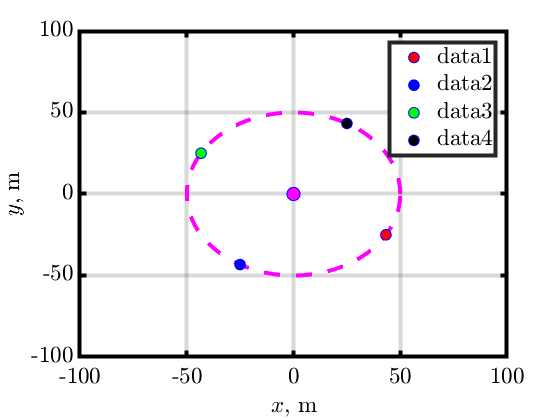

axis(ax1,[-100 100 -100 100 0 10])

% figure(2)
% plot(te,r1 ,'r','LineWidth',lw);hold on; grid on;
% plot(te,r2 ,'g','LineWidth',lw);hold on;grid on;
% plot(te,r3 ,'b','LineWidth',lw);hold on; grid on;
% plot(te,r4 ,'k','LineWidth',lw);hold on; grid on;
% ax2 = gca;
% ax2.FontSize = ax_fnt;
% ax2.XColor = 'black';         % Box horizontal lines' color
% ax2.YColor = 'black';         % Box vertical lines' color
% set(ax2,'linewidth',3)
% xlabel(ax2,' $t$,  s','Fontsize',lbl_fnt)
% ylabel(ax2,'Radial distance $$ r $$, m','Fontsize',lbl_fnt)


% figure(3)
% plot(te,alpha1 ,'r','LineWidth',lw);hold on; grid on;
% plot(te,alpha2 ,'g','LineWidth',lw);hold on; grid on;
% plot(te,alpha3 ,'b','LineWidth',lw);hold on; grid on;
% ax3 = gca;
% ax3.FontSize = ax_fnt;
% ax3.XColor = 'black';         % Box horizontal lines' color
% ax3.YColor = 'black';         % Box vertical lines' color
% set(ax3,'linewidth',3)
% xlabel(ax3,' $t$,  s','Fontsize',lbl_fnt)
% ylabel(ax3,'LOS angle $$ \theta $$, radian','Fontsize',lbl_fnt)

% fig = gcf;
% fig.WindowState = 'maximized';
% fig.Position = [10 50 1000 950];
% ax1 = gca;
h14 = plot(ax1,x(1,1),x(1,2),'ob','MarkerSize',8,'MarkerFaceColor','red');hold(ax1,'on');grid(ax1,'on');
h15 = plot(ax1,x(1,3),x(1,4),'ob','MarkerSize',8,'MarkerFaceColor','blue');hold(ax1,'on');grid(ax1,'on');
h16 = plot(ax1,x(1,5),x(1,6),'ob','MarkerSize',8,'MarkerFaceColor','green');hold(ax1,'on');grid(ax1,'on');
h18 = plot(ax1,x(1,7),x(1,8),'ob','MarkerSize',8,'MarkerFaceColor','black');hold(ax1,'on');grid(ax1,'on');
% h19 = plot(ax1,[xt1(1,1) xt3(1,1)],[yt1(1,1) yt3(1,1)],'--r','LineWidth',2);hold on;grid on;
% h15 = plot(ax1,xt1(1,1),yt1(1,1),'--r','LineWidth',4);hold on;grid on;
% h16 = plot(ax1,xt2(1,1),yt2(1,1),'--b','LineWidth',4);hold on;grid on;
% h17 = plot(ax1,xt3(1,1),yt3(1,1),'--k','LineWidth',4);hold on;grid on;
% h20 = plot(ax1,xt4(1,1),yt4(1,1),'--k','LineWidth',4);hold on;grid on;
% ax1.FontSize = 18;
% % Outer box setup
% box on                        % Switch on the box around the axis 
% ax1.XColor = 'black';         % Box horizontal lines' color
% ax1.YColor = 'black';         % Box vertical lines' color
% set(ax1,'linewidth',3)
% xlabel(ax1,' $$ x, $$  m','Fontsize',18);
% ylabel(ax1,'$$ y, $$  m','Fontsize',18);
% axis(ax1,'equal')

for i = 1 :length(x)
%     if i==1
     set(h11,'XData',x(i,1),'YData',x(i,2));hold(ax1,'on');grid(ax1,'on');
     set(h12,'XData',x(i,3),'YData',x(i,4));hold(ax1,'on');grid(ax1,'on');
     set(h13,'XData',x(i,5),'YData',x(i,6));hold(ax1,'on');grid(ax1,'on');
     set(h17,'XData',x(i,7),'YData',x(i,8));hold(ax1,'on');grid(ax1,'on');
     set(h14,'XData',x(i,1),'YData',x(i,2));hold(ax1,'on');grid(ax1,'on');
     set(h15,'XData',x(i,3),'YData',x(i,4));hold(ax1,'on');grid(ax1,'on');
     set(h16,'XData',x(i,5),'YData',x(i,6));hold(ax1,'on');grid(ax1,'on');
     set(h18,'XData',x(i,7),'YData',x(i,8));hold(ax1,'on');grid(ax1,'on');
%     else
%      set(h11,'XData',x(i,1),'YData',x(i,2));hold(ax1,'on');grid(ax1,'on');
%      set(h12,'XData',x(i,3),'YData',x(i,4));hold(ax1,'on');grid(ax1,'on');
%      set(h13,'XData',x(i,5),'YData',x(i,6));hold(ax1,'on');grid(ax1,'on');
%      set(h14,'XData',x(i,1),'YData',x(i,2));hold(ax1,'on');grid(ax1,'on');
%      set(h15,'XData',x(i,3),'YData',x(i,4));hold(ax1,'on');grid(ax1,'on');
%      set(h16,'XData',x(i,5),'YData',x(i,6));hold(ax1,'on');grid(ax1,'on');  
%     end
     
     drawnow
    
end

function out = fun_circular(t,x)
global k1  rd wd xc yc alpha1 alpha2 alpha3 r1 r2 r3 te alpha4 r4
if t ==0
    r1 = [];
    r2 = [];
    r3 = [];
    r4 = [];
    te = [];
    alpha1 = [];
    alpha2 = [];
    alpha3 = [];
    alpha4 = [];
end
rho1 = sqrt((x(1)-xc)^2 + (x(2)-yc).^2) ;
theta1 = atan2(x(2),x(1));

rho2 = sqrt((x(3)-xc)^2 + (x(4)-yc).^2) ;
theta2 = atan2(x(4),x(3));

rho3 = sqrt((x(5)-xc)^2 + (x(6)-yc).^2) ;
theta3 = atan2(x(6),x(5));

rho4 = sqrt((x(7)-xc)^2 + (x(8)-yc).^2) ;
theta4 = atan2(x(8),x(7));

e1 = rho1 - rd ;
e2 = rho2 - rd ;
e3 = rho3 - rd ;
e4 = rho4 - rd ;
% e2 = rho2 - rd ;
% e3 = rho3 - rd ;

a12 = 1;a13 = a12; a14 = a12;
a21 = a12; a23 = a12; a24 = a12;
a31 = a12; a32 = a12; a34 = a12;
a41 = a12; a42 = a12; a43 = a12;


beta_12 = pi/2;
beta_13 = 2*pi/2 ;
beta_14 = 3*pi/2 ;
beta_21 = -pi/2 ;
beta_23 = pi/2 ;
beta_24 = 2*pi/2 ;
beta_31 = -2*pi/2 ;
beta_32 = -pi/2 ;
beta_34 = pi/2 ;
beta_41 = -3*pi/2 ;
beta_42 = -2*pi/2 ;
beta_43 = -pi/2 ;

k11 = 1; k21 = 1.05; k31 = 3; k41 = 5;

h1 = k1*a12*sin(theta1-theta2 - beta_12) + k1*a13*sin(theta1-theta3- beta_13) + k1*a14*sin(theta1-theta4- beta_14);
h2 = k1*a21*sin(theta2-theta1- beta_21) + k1*a23*sin(theta2-theta3 - beta_23) + k1*a24*sin(theta2-theta4 - beta_24);
h3 = k1*a31*sin(theta3-theta1- beta_31) + k1*a32*sin(theta3-theta2 - beta_32) + k1*a34*sin(theta3-theta4 - beta_34);
h4 = k1*a41*sin(theta4-theta1- beta_41) + k1*a42*sin(theta4-theta2 - beta_42) + k1*a43*sin(theta4-theta3 - beta_43);

out(1,1) = -k11*e1*cos(theta1) - rd*(wd + h1)*(-sin(theta1));
out(2,1) = -k11*e1*sin(theta1) - rd*(wd + h1)*(cos(theta1));

out(3,1) = -k21*e2*cos(theta2) - rd*(wd + h2)*(-sin(theta2));
out(4,1) = -k21*e2*sin(theta2) - rd*(wd + h2)*(cos(theta2));

out(5,1) = -k31*e3*cos(theta3) - rd*(wd + h3)*(-sin(theta3));
out(6,1) = -k31*e3*sin(theta3) - rd*(wd + h3)*(cos(theta3));

out(7,1) = -k41*e4*cos(theta4) - rd*(wd + h4)*(-sin(theta4));
out(8,1) = -k41*e4*sin(theta4) - rd*(wd + h4)*(cos(theta4));
% 
% kz1 = 5;h = 0.02;
% out(9,1) = kz1*(h - x(9));
% out(10,1) = kz1*(h - x(10));
% out(11,1) = kz1*(h - x(11));
% out(12,1) = kz1*(h - x(12));

 r1 = [r1 rho1];
 r2 = [r2 rho2];
 r3 = [r3 rho3];
 r4 = [r4 rho4];
 te = [te t];
 
 alpha1 = [alpha1 theta1];
 alpha2 = [alpha2 theta2];
 alpha3 = [alpha3 theta3];
 alpha4 = [alpha4 theta4];

end